dataDir = fullfile('./', 'Daten', 'Galaxies'); 
ellipticalDir = fullfile(dataDir, 'elliptic');
spiralDir = fullfile(dataDir, 'spiral');
irregularDir = fullfile(dataDir, 'irregular');

lbl_e(1:268) = categorical("elliptic");
lbl_e(269:268+233) = categorical("spiral");
lbl_e(268+233+1:1076) = categorical("irregular");


ans = 3×1 cell array
    {'elliptic' }
    {'spiral'   }
    {'irregular'}


lbl_e = 1×1076 categorical array
  Columns 1 through 731

     elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic      elliptic     



imds = imageDatastore(dataDir, "IncludeSubfolders", true, "Labels", lbl_e);

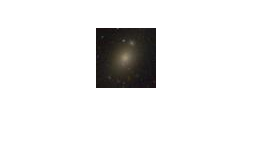

img_e = readimage(imds, 1);
imshow(img_e);

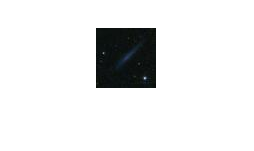

img_s = readimage(imds, 269);
imshow(img_s);

[imds_train, imds_test] = splitEachLabel(imds, 0.8);

layers = [
    imageInputLayer([60 60 3])
    convolution2dLayer(8, 96)
    reluLayer
    averagePooling2dLayer(3)
    fullyConnectedLayer(24)
    reluLayer
    fullyConnectedLayer(3)
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
];
options = trainingOptions('adam', 'MaxEpochs', 50, 'InitialLearnRate', 0.01, 'MiniBatchSize', 64, 'Plots', 'training-progress', 'Shuffle', 'every-epoch');
net_gala = trainNetwork(imds_train, layers, options);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       39.06% |       1.2162 |          0.0100 |
|       4 |          50 |       00:00:00 |       89.06% |       0.3756 |          0.0100 |
|       8 |         100 |       00:00:01 |       95.31% |       0.2298 |          0.0100 |
|      12 |         150 |       00:00:02 |       90.62% |       0.2453 |          0.0100 |
|      16 |         200 |       00:00:02 |       95.31% |       0.1686 |          0.0100 |
|      20 |         250 |       00:00:03 |       92.19% |       0.1792 |          0.0100 |
|      24 |         300 |  

tic
[pred, mat] = classify(net_gala, imds_test);
toc

Elapsed time is 0.026094 seconds.



testErr = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);

aug = imageDataAugmenter('RandRotation', [0, 360], ...
   'RandScale', [0.5, 1.2], ...
   'RandXTranslation', [-50, 50], ...
   'RandYTranslation', [-50, 50], ...
   'FillValue', 70*[1,1,1], ...
   'RandXReflection', true, 'RandYReflection', true);

augimds = augmentedImageDatastore([60 60 3], imds, 'DataAugmentation',augmenter);
net_gala_aug = trainNetwork(augimds, layers, options);